% data = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/COVID/CC_COVID/Confirmed_Cases_CC.csv', 'ReadVariableNames',1);
% dates = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/COVID/CC_COVID/Confirmed_Cases_CC.csv');
% Confounding = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/Confounding/Confounding_Dataset.csv', 'ReadVariableNames',1);

data = readtable('Datasets/COVID/CC_COVID/Confirmed_Cases_CC.csv', 'ReadVariableNames',1);
dates = readtable('Datasets/COVID/CC_COVID/Confirmed_Cases_CC.csv');
Confounding = readtable('Datasets/Confounding/Confounding_Dataset.csv', 'ReadVariableNames',1);

Total_Population = (Confounding.TOT_POP);
cases = table2array(data(:,12:173));
cases = cases./Total_Population;

US = 1024;
[rC, cC] = size(cases);
splines = zeros(rC,US);

for t = 1:rC
    casesS = cases(t,:);
    casesS = nonzeros(casesS); % non-zero cases 
    if length(casesS)>1
        x = [1:length(casesS)]';  % number of days since first case 
        f = fit(x, casesS, 'cubicinterp');
        xeval = linspace(1, length(casesS), US);
        sp_eval = f(xeval)';
        splines(t,:)= sp_eval;
    end 
end 

% Linear Correlation btwn cases
xcor_prenorm = corrcoef(splines');
NodeNames = string([1:rC]);
NodeNames = cellstr(NodeNames);

%xcor_total = 0.99999-abs(xcor_total);
new_diag = zeros(1,rC);
xcor_prenorm(find(eye(size(xcor_prenorm))))=new_diag; %removing self edges

G_PRENORM = graph(xcor_prenorm, NodeNames);
%plot(G_PRENORM, 'NodeLabel', NodeNames)

G_PRENORM_WEIGHTS = abs(G_PRENORM.Edges.Weight);
h = histogram(G_PRENORM_WEIGHTS);
hold on; 
title('Pre Re-Mapping')
hval = h.Values;
hedge = h.BinEdges;
hedge = hedge(2:length(hedge));

[hfit, hgof] = fit(hedge', hval', 'exp1')

hfit =      General model Exp1:
     hfit(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =       10.91  (3.858, 17.95)
       b =       7.793  (7.107, 8.478)

hgof = struct with fields:
           sse: 2.3240e+08
       rsquare: 0.9401
           dfe: 98
    adjrsquare: 0.9394
          rmse: 1.5399e+03


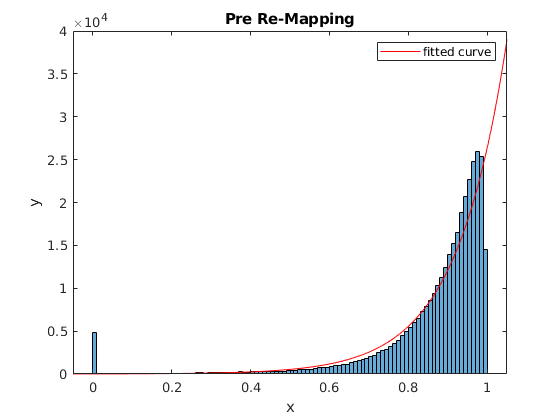

plot(hfit)
hold off;

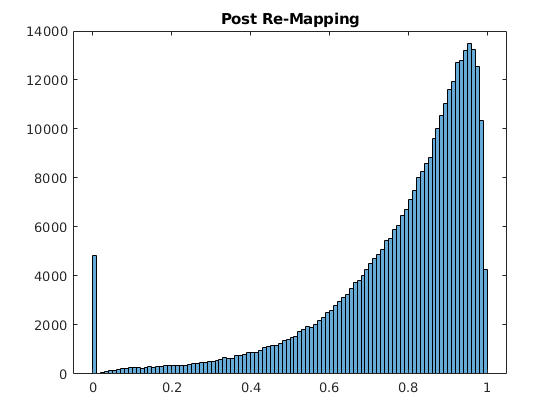


t = G_PRENORM_WEIGHTS.^2;
histogram(t)
title('Post Re-Mapping')

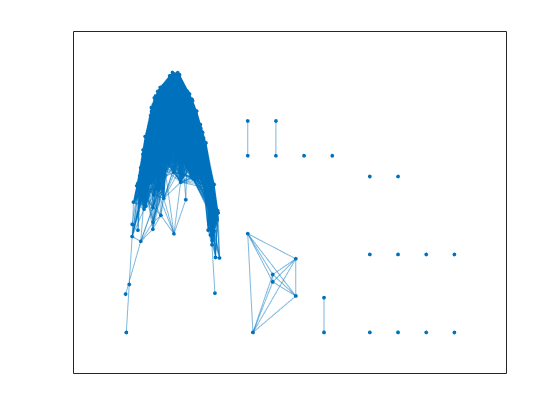

% Remap Correlation values 
xcor_RM = xcor_prenorm.^2;
xcor_threshRM = xcor_RM;
xcor_threshRM(xcor_threshRM<0.9)=0;
t = graph(xcor_threshRM);
plot(t)

xcor_total = 0.99999-abs(xcor_prenorm);
new_diag = zeros(1,rC);
xcor_total(find(eye(size(xcor_total))))=new_diag %removing self edges

xcor_total =          0    0.0428    0.0125    0.0115    0.0275    0.0154    0.0466    0.0164    0.0639    0.0909    0.0436    0.0109    0.0608    0.0649    0.0395    0.1275    0.0187    0.1455    0.1024    0.1268    0.0300    0.0275    0.0435    0.0682    0.1319    0.0200    0.1179    0.0592    0.0284    0.1254    0.1252    0.0154    0.0434    0.1359    0.0207    0.0798    0.0780    0.0339    0.2487    0.0073    0.0223    0.0425    0.1357    0.0374    0.0972    0.0990    0.0282    0.0774    0.0507    0.0643
    0.0428         0    0.0192    0.0413    0.0083    0.0182    0.0677    0.0297    0.0090    0.0354    0.0144    0.0385    0.0501    0.0200    0.0115    0.1144    0.0198    0.1407    0.0358    0.1247    0.0117    0.0044    0.0444    0.0669    0.0707    0.0314    0.0633    0.0664    0.0147    0.2513    0.0553    0.0197    0.0183    0.0876    0.0077    0.0531    0.0485    0.0600    0.3112    0.0232    0.0166    0.0212    0.1328    0.0513    0.0408    0.1805    0.0067    0.0118    0.

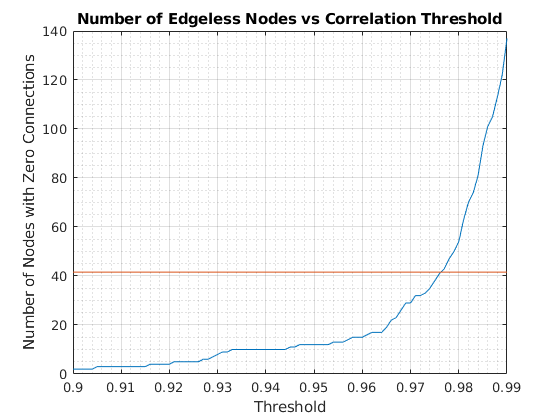

threshL = [0.01:0.001:0.1];
num_zero_connections = zeros(size(threshL));

for t=1:length(threshL)
    xcor_thresh = xcor_total;
    xcor_thresh(xcor_thresh>threshL(t))=0;
    G = graph(xcor_thresh);
    D = degree(G);
    zero_con_idx = find(D==0);
    num_zero_connections(t) = length(zero_con_idx);
end 

five_pct = (832*0.05)*ones(size(threshL));
plot(1-threshL, num_zero_connections)
hold on; 
plot(1-threshL, five_pct)
xlabel('Threshold')
ylabel('Number of Nodes with Zero Connections')
title('Number of Edgeless Nodes vs Correlation Threshold')
hold off; 
grid on; 
grid minor; 

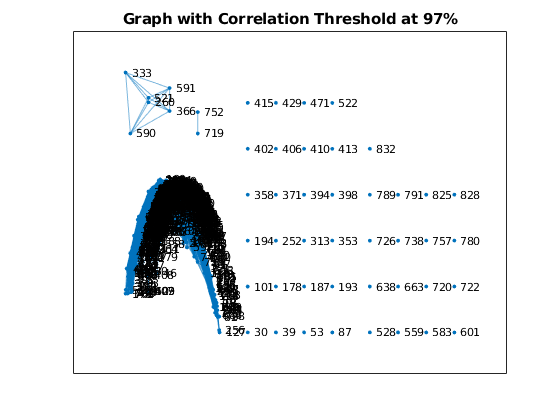

xcor_thresh = xcor_total;
xcor_thresh(xcor_thresh>0.0237)=0;
G = graph(xcor_thresh);
D = degree(G);
plot(G, 'NodeLabel', NodeNames);
title('Graph with Correlation Threshold at 97%')

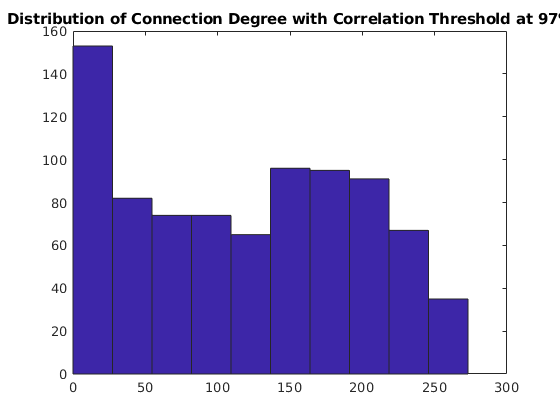

hist(D);
title('Distribution of Connection Degree with Correlation Threshold at 97%')

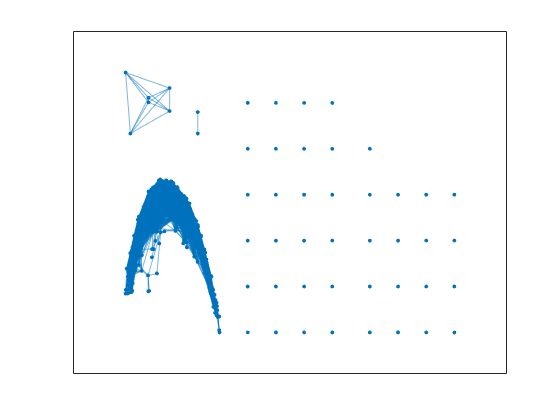

xcor_mod = xcor_total;
thresh = 0.0237;
xcor_mod(xcor_mod>thresh)=0;

G_MOD = graph(xcor_mod, NodeNames);
p = plot(G_MOD);


bins = conncomp(G_MOD);

Group1 = subgraph(G_MOD, find(bins==12));
G1_idx = str2double(table2array(Group1.Nodes))

G1_idx =    260
   333
   366
   521
   590
   591


Outliers = subgraph(G_MOD, find(bins ~= 12 & bins ~= 1));
Out_idx = str2double(table2array(Outliers.Nodes));

classifications = zeros(832,4);
classifications(Out_idx,:) = 1;
classifications(G1_idx,:) = 2;
LSUB = subgraph(G_MOD, find(bins == 1));

%plot(Group1)
%plot(Outliers)
%plot(LSUB)

## Time to cluster the large subgroup - spectral clustering

SC_Whole = spectralcluster(splines,3);
classifications(:,1)=SC_Whole;

LSUB_Sim = adjacency(LSUB, 'weighted');
LSUB_Sim_Full = full(LSUB_Sim);

% LSUB into 3 Groups 
SC3_LSUB = spectralcluster(LSUB_Sim_Full,3);

SC3_C1 = subgraph(LSUB, find(SC3_LSUB==1));
SC3_C1_idx = str2double(table2array(SC3_C1.Nodes));
classifications(SC3_C1_idx,2)=3;

SC3_C2 = subgraph(LSUB, find(SC3_LSUB==2));
SC3_C2_idx = str2double(table2array(SC3_C2.Nodes));
classifications(SC3_C2_idx,2)=4;

SC3_C3 = subgraph(LSUB, find(SC3_LSUB==3));
SC3_C3_idx = str2double(table2array(SC3_C3.Nodes));
classifications(SC3_C3_idx,2)=5;


% LSUB into 4 Groups 
SC4_LSUB = spectralcluster(LSUB_Sim_Full,4);

SC4_C1 = subgraph(LSUB, find(SC4_LSUB==1));
SC4_C1_idx = str2double(table2array(SC4_C1.Nodes));
classifications(SC4_C1_idx,3)=3;

SC4_C2 = subgraph(LSUB, find(SC4_LSUB==2));
SC4_C2_idx = str2double(table2array(SC4_C2.Nodes));
classifications(SC4_C2_idx,3)=4;

SC4_C3 = subgraph(LSUB, find(SC4_LSUB==3));
SC4_C3_idx = str2double(table2array(SC4_C3.Nodes));
classifications(SC4_C3_idx,3)=5;

SC4_C4 = subgraph(LSUB, find(SC4_LSUB==4));
SC4_C4_idx = str2double(table2array(SC4_C4.Nodes));
classifications(SC4_C4_idx,3)=6;

% LSUB into 5 Groups 
SC5_LSUB = spectralcluster(LSUB_Sim_Full,5);
SC5_C1 = subgraph(LSUB, find(SC5_LSUB==1));
SC5_C1_idx = str2double(table2array(SC5_C1.Nodes));
classifications(SC5_C1_idx,4)=3;

SC5_C2 = subgraph(LSUB, find(SC5_LSUB==2));
SC5_C2_idx = str2double(table2array(SC5_C2.Nodes));
classifications(SC5_C2_idx,4)=4;

SC5_C3 = subgraph(LSUB, find(SC5_LSUB==3));
SC5_C3_idx = str2double(table2array(SC5_C3.Nodes));
classifications(SC5_C3_idx,4)=5;

SC5_C4 = subgraph(LSUB, find(SC5_LSUB==4));
SC5_C4_idx = str2double(table2array(SC5_C4.Nodes));
classifications(SC5_C4_idx,4)=6;

SC5_C5 = subgraph(LSUB, find(SC5_LSUB==5));
SC5_C5_idx = str2double(table2array(SC5_C5.Nodes));
classifications(SC5_C5_idx,4)=7;

T = data;
T.SpectralClusteringWhole = classifications(:,1);
T.SpectralClusteringK3 = classifications(:,2);
T.SpectralClusteringK4 = classifications(:,3);
T.SpectralClusteringK5 = classifications(:,4);

%T = table(SpectralClusteringWhole,SpectralClusteringK3,SpectralClusteringK4,SpectralClusteringK5)
writetable(T,'Datasets/Spectral_Clustering_Classes.csv')